# **QEA Robo _Bridge of Doom**

### **Exercise 36-1. Plot Parametric Curve**

%For this code, we will going to plot a parametric curve that defines the
%centerline of the bridge.

%First we must define the symbolic variable we will being using
syms u 

%Define the equation for the curve. Created the individual equations for r
%in the i, j, and k direction then packed them in one 1 x 3 vector. 
ri=4 * 0.3960 * cos(2.65 * (u + 1.4));
rj=4*(- 0.99 * sin(u + 1.4));
rk=0*u;
r=[ri,rj,rk];

%Using diff function to find the derivative of r 
dr=diff(r,u);

%Making assumptions to make the following equations look clean
assume(u,{'real','positive'})

%Finding the unit tangent vector and simplify it using simplify function
T_hat_ugly=dr./norm(dr)

$$T\_hat\_ugly = \begin{array}{l} \left(\begin{array}{ccc} -\frac{5247\,\sin\left(\frac{53\,u}{20}+\frac{371}{100}\right)}{1250\,\sigma_{1}} & -\frac{99\,\cos\left(u+\frac{7}{5}\right)}{25\,\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\frac{27531009\,{\left|\sin\left(\frac{53\,u}{20}+\frac{371}{100}\right)\right|}^{2}}{1562500}+\frac{9801\,{\left|\cos\left(u+\frac{7}{5}\right)\right|}^{2}}{625}} \end{array}$$

T_hat=simplify(T_hat_ugly)

$$T\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{53\,\sin\left(\frac{53\,u}{20}+\frac{371}{100}\right)}{\sigma_{1}} & -\frac{50\,\cos\left(u+\frac{7}{5}\right)}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2500\,{\cos\left(u+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,u}{20}+\frac{371}{100}\right)}^{2}} \end{array}$$


%Finding the unit normal vector and simplify it using simplify function
dT_hat=diff(T_hat,u);
N_hat=dT_hat/norm(dT_hat);
N_hat=simplify(N_hat)

$$N\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{2\,\left(483625\,\sigma_{6}+702250\,\sigma_{5}+218625\,\sigma_{4}\right)}{\sigma_{1}} & \frac{561800\,\sin\left(u+\frac{7}{5}\right)+1025285\,\sigma_{3}+463485\,\sigma_{2}}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=265\,\sqrt{2809\,{\left(40\,\sin\left(u+\frac{7}{5}\right)+73\,\sigma_{3}+33\,\sigma_{2}\right)}^{2}+2500\,{\left(73\,\sigma_{6}+106\,\sigma_{5}+33\,\sigma_{4}\right)}^{2}}\\ \sigma_{2}=\sin\left(\frac{63\,u}{10}+\frac{441}{50}\right)\\ \sigma_{3}=\sin\left(\frac{43\,u}{10}+\frac{301}{50}\right)\\ \sigma_{4}=\cos\left(\frac{93\,u}{20}+\frac{651}{100}\right)\\ \sigma_{5}=\cos\left(\frac{53\,u}{20}+\frac{371}{100}\right)\\ \sigma_{6}=\cos\left(\frac{13\,u}{20}+\frac{91}{100}\right) \end{array}$$


%Finding the unit binormal vector with cross product of unit tangent vector
%and unit normal vector
B_hat=cross(T_hat,N_hat);
B_hat=simplify(B_hat)

$$B\_hat = \begin{array}{l} \left(\begin{array}{ccc} 0 & 0 & -\frac{91250\,\cos\left(\frac{7\,u}{20}+\frac{49}{100}\right)+\frac{764917\,\cos\left(\frac{33\,u}{20}+\frac{231}{100}\right)}{2}+\frac{327837\,\cos\left(\frac{73\,u}{20}+\frac{511}{100}\right)}{2}+41250\,\cos\left(\frac{113\,u}{20}+\frac{791}{100}\right)-\frac{205057\,\cos\left(\frac{139\,u}{20}+\frac{973}{100}\right)}{2}-\frac{92697\,\cos\left(\frac{179\,u}{20}+\frac{1253}{100}\right)}{2}}{\sqrt{2809\,{\left(40\,\sin\left(u+\frac{7}{5}\right)+73\,\sin\left(\frac{43\,u}{10}+\frac{301}{50}\right)+33\,\sin\left(\frac{63\,u}{10}+\frac{441}{50}\right)\right)}^{2}+2500\,{\left(73\,\cos\left(\frac{13\,u}{20}+\frac{91}{100}\right)+106\,\cos\left(\sigma_{1}\right)+33\,\cos\left(\frac{93\,u}{20}+\frac{651}{100}\right)\right)}^{2}}\,\sqrt{2500\,{\cos\left(u+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\sigma_{1}\right)}^{2}}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{53\,u}{20}+\frac{371}{100} \end{array}$$

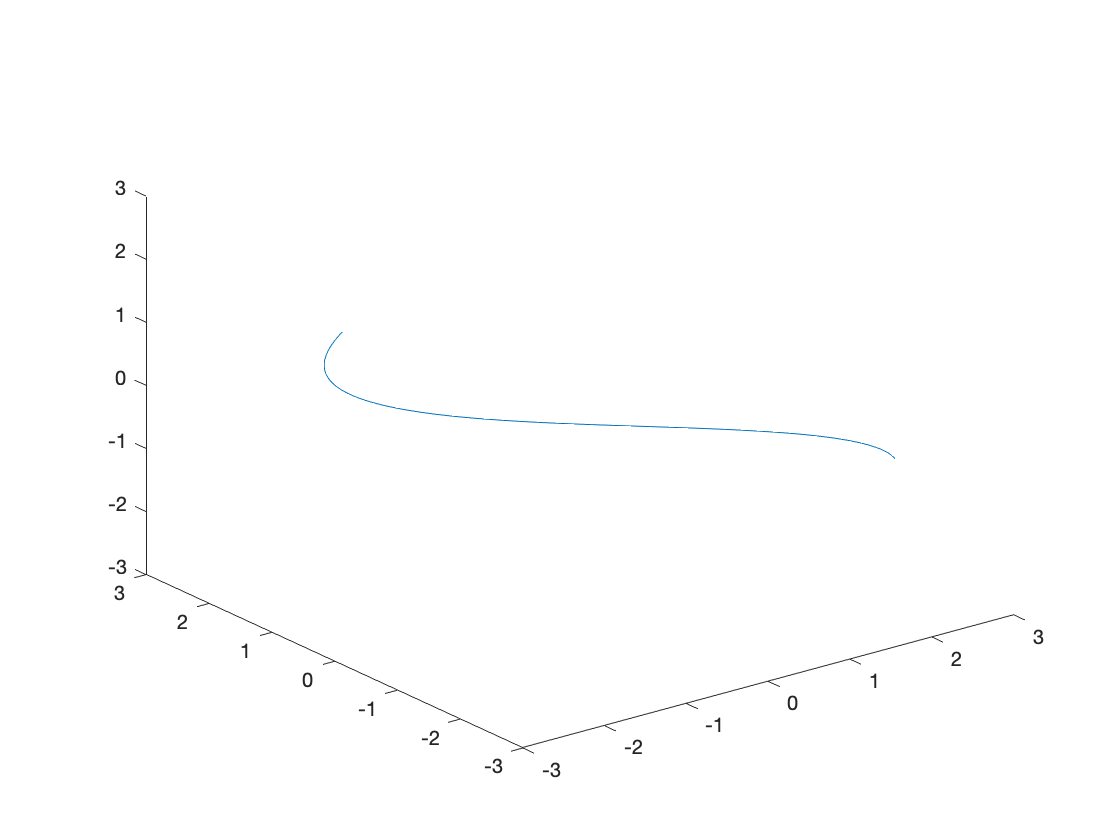


%Making substitution of the symbolic variable to visualize the curve. 
u_num = linspace(0,3.2); 

%Substituting u into the curve, unit tangent vector, unit normal vector, and unit binormal vector
%equations as type double and plotting them in 3D. 
for n=1:length(u_num)
    r_num(n,:)=double(subs(r,[u],[u_num(n)]));
    T_hat_num(n,:)=double(subs(T_hat,[u],[u_num(n)]));
    N_hat_num(n,:)=double(subs(N_hat,[u],[u_num(n)]));
    B_hat_num(n,:)=double(subs(B_hat,[u],[u_num(n)]));
    
    plot3(r_num(:,1),r_num(:,2),r_num(:,3)), axis([-3 3 -3 3 -3 3]),hold on % plot the entire curve
    quiver3(r_num(n,1),r_num(n,2),r_num(n,3),T_hat_num(n,1),T_hat_num(n,2),T_hat_num(n,3),'r') % plot the unit tangent
    quiver3(r_num(n,1),r_num(n,2),r_num(n,3),N_hat_num(n,1),N_hat_num(n,2),N_hat_num(n,3),'b') % plot the unit normal
    quiver3(r_num(n,1),r_num(n,2),r_num(n,3),B_hat_num(n,1),B_hat_num(n,2),B_hat_num(n,3),'g'), hold off % plot the unit binormal
    drawnow 
end

### **Exercise 36-2&3. Plot Wheel Velocities, Linear Speed, and Angular Velocity**

%Defining the symbolic variable (T is time, d is the distance between the
%two wheels, and B is the speed)
syms t d B

%Defining the equation for the motion and the derivative.
ri=4 * (0.3960 * cos(2.65 * (B*t+ 1.4)));
rj=4*(- 0.99 * sin(B*t + 1.4));
rk = 0*t

$$rk = 0$$

r=[ri,rj,rk];

diffrt=diff(r,t);

%Making assumptions to make the following equations look clean
assume(t,{'real','positive'})
assume(d,{'real','positive'})
assume(B,{'real','positive'})

%Finding the linear speed of the motion
maglist = [diffrt]

$$maglist = \left(\begin{array}{ccc} -\frac{5247\,B\,\sin\left(\frac{53\,B\,t}{20}+\frac{371}{100}\right)}{1250} & -\frac{99\,B\,\cos\left(B\,t+\frac{7}{5}\right)}{25} & 0 \end{array}\right)$$

mag = norm(maglist)

$$mag = \sqrt{\frac{9801\,B^{2}\,{\left|\cos\left(B\,t+\frac{7}{5}\right)\right|}^{2}}{625}+\frac{27531009\,B^{2}\,{\left|\sin\left(\frac{53\,B\,t}{20}+\frac{371}{100}\right)\right|}^{2}}{1562500}}$$

V = mag

$$V = \sqrt{\frac{9801\,B^{2}\,{\left|\cos\left(B\,t+\frac{7}{5}\right)\right|}^{2}}{625}+\frac{27531009\,B^{2}\,{\left|\sin\left(\frac{53\,B\,t}{20}+\frac{371}{100}\right)\right|}^{2}}{1562500}}$$


%Finding the unit tangent and unit normal vectors
Unit_Tangent=simplify(diffrt./norm(diffrt))

$$Unit\_Tangent = \begin{array}{l} \left(\begin{array}{ccc} -\frac{53\,\sin\left(\frac{53\,B\,t}{20}+\frac{371}{100}\right)}{\sigma_{1}} & -\frac{50\,\cos\left(B\,t+\frac{7}{5}\right)}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2500\,{\cos\left(B\,t+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,B\,t}{20}+\frac{371}{100}\right)}^{2}} \end{array}$$

Dir_Tangent=diff(Unit_Tangent,t);

Unit_Normal = simplify(Dir_Tangent)/norm(Dir_Tangent)

$$Unit\_Normal = \begin{array}{l} \left(\begin{array}{ccc} -\frac{6625\,\sqrt{2}\,B\,\left(73\,\cos\left(\frac{13\,B\,t}{20}+\frac{91}{100}\right)+106\,\cos\left(\sigma_{5}\right)+33\,\cos\left(\frac{93\,B\,t}{20}+\frac{651}{100}\right)\right)}{2\,\sigma_{2}\,\sigma_{1}} & \frac{14045\,\sqrt{2}\,B\,\left(40\,\sin\left(\sigma_{6}\right)+73\,\sin\left(\frac{43\,B\,t}{10}+\frac{301}{50}\right)+33\,\sin\left(\frac{63\,B\,t}{10}+\frac{441}{50}\right)\right)}{4\,\sigma_{2}\,\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(2500\,\cos\left(2\,B\,t+\frac{14}{5}\right)-2809\,\cos\left(\frac{53\,B\,t}{10}+\frac{371}{50}\right)+5309\right)}^{3/2}\\ \sigma_{2}=\sqrt{{\left|\frac{25\,\cos\left(\sigma_{6}\right)\,\sigma_{3}}{{\sigma_{4}}^{3/2}}-\frac{50\,B\,\sin\left(\sigma_{6}\right)}{\sqrt{\sigma_{4}}}\right|}^{2}+{\left|\frac{53\,\sin\left(\sigma_{5}\right)\,\sigma_{3}}{2\,{\sigma_{4}}^{3/2}}+\frac{2809\,B\,\cos\left(\sigma_{5}\right)}{20\,\sqrt{\sigma_{4}}}\right|}^{2}}\\ \sigma_{3}=5000\,B\,\cos\left(\sigma_{6}\right)\,\sin\left(\sigma_{6}\right)-\frac{148877\,B\,\cos\left(\sigma_{5}\right)\,\sin\left(\sigma_{5}\right)}{10}\\ \sigma_{4}=2500\,{\cos\left(\sigma_{6}\right)}^{2}+2809\,{\sin\left(\sigma_{5}\right)}^{2}\\ \sigma_{5}=\frac{53\,B\,t}{20}+\frac{371}{100}\\ \sigma_{6}=B\,t+\frac{7}{5} \end{array}$$


%Finding the angular velocity using the cross product of the unit tangent
%vector and the direction of the unit tangent vector
omega=simplify(cross(Unit_Tangent,Dir_Tangent))

$$omega = \left(\begin{array}{ccc} 0 & 0 & -\frac{265\,B\,\left(73\,\cos\left(\frac{33\,B\,t}{20}+\frac{231}{100}\right)+33\,\cos\left(\frac{73\,B\,t}{20}+\frac{511}{100}\right)\right)}{5000\,\cos\left(2\,B\,t+\frac{14}{5}\right)-5618\,\cos\left(\frac{53\,B\,t}{10}+\frac{371}{50}\right)+10618} \end{array}\right)$$


%Finding the velocity of left and right wheel using the linear velocity and
%angular velocity
vl = simplify (V - d/2*omega(3));
vr = simplify (V + d/2*omega(3));

%Making substitution of the symbolic variables. Since the maximum value of u=3.2
%and u=B*t, the maximum value of t will be 32.
t_num = linspace(0,32,32)

t_num =          0    1.0323    2.0645    3.0968    4.1290    5.1613    6.1935    7.2258    8.2581    9.2903   10.3226   11.3548   12.3871   13.4194   14.4516   15.4839   16.5161   17.5484   18.5806   19.6129   20.6452   21.6774   22.7097   23.7419   24.7742   25.8065   26.8387   27.8710   28.9032   29.9355   30.9677   32.0000


B_num = 0.1

B_num = 0.1000

d_num = 0.235

d_num = 0.2350

tx = t_num'

tx =          0
    1.0323
    2.0645
    3.0968
    4.1290
    5.1613
    6.1935
    7.2258
    8.2581
    9.2903



%Substituting the t_num, B_num, d_num into existing equations
for n=1:length(t_num)
    vl_num(n,:)=double(subs(vl,[t,d,B],[t_num(n),d_num,B_num]));
    vr_num(n,:)=double(subs(vr,[t,d,B],[t_num(n),d_num,B_num]));
    omega_num(n,:)=double(subs(omega,[t,d,B],[t_num(n),d_num, B_num]));
    lin_vel(n,:)=double(subs(V,[t,d,B],[t_num(n),d_num, B_num]));
end


%After simulating the NEATO and collecting the data, we analyzed the
%experimental data. 

%Loading the collected data and extracting time and position (distance
%traveled) of the left and right wheel to each variable. 
load dataset.mat
timeframe=dataset(:,1)

timeframe =          0
         0
         0
         0
    1.0760
    1.1740
    1.2730
    1.3740
    1.6550
    1.6730


leftpos=dataset(:,2)

leftpos =     4.6836
    4.6836
    4.6836
    4.6836
    4.6836
    4.6836
    4.6836
    4.6836
    4.6836
    4.6836


rightpos=dataset(:,3)

rightpos =     3.1555
    3.1555
    3.1555
    3.1555
    3.1555
    3.1555
    3.1555
    3.1555
    3.1555
    3.1555



%Using the equation of velocity=position/time, finding the velocities of
%the left and right wheel.
leftvelo=diff(leftpos)./diff(timeframe);
rightvelo=diff(rightpos)./diff(timeframe);

%With the velocities of each wheel, we can calculate the linear and angular
%velocity
velo_exp=(leftvelo+rightvelo)./2

velo_exp =       -Inf
      -Inf
      -Inf
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0000


angular_exp=(rightvelo-leftvelo)./0.235

angular_exp =        NaN
       NaN
       NaN
    0.0000
   -0.0000
         0
   -0.0000
   -0.0000
   -0.0001
    0.0000



%Reshaping the matrices so they match the size of the predicted data and
%can be plotted together.
avgleft=(mean(reshape(leftvelo,10,[])))';

Error using reshape
Product of known dimensions, 10, not divisible into total number of elements, 42.

avgright=(mean(reshape(rightvelo,10,[])))';
avgvelo = (mean(reshape(velo_exp,10,[])))';
angularvelo = (mean(reshape(angular_exp,10,[])))';


%Plotting the theoretical and experimental path
figure(1)
title('Theoretical vs Experimental Right Wheel Velocity')
plot(tx(:,1),vr_num(:,1))
hold on
plot(tx(:,1),avgright(:,1),'--m')
xlabel('Time(s)') 
ylabel('Velocity(m/s)') 
legend('theoretical','experimental')

%Plotting the theoretical and experimental left wheel velocity
figure(2)
title('Theoretical vs Experimental Left Wheel Velocity')
plot(tx(:,1),vl_num(:,1))
hold on
plot(tx(:,1),avgleft(:,1),'--m')
xlabel('Time(s)') 
ylabel('Velocity(m/s)') 
legend('theoretical','experimental')

%Plotting the theoretical and experimental right wheel velocity
figure(3)
title('Theoretical vs Experimental Robot Angular Velocity')
plot(tx(:,1),omega_num(:,3))
hold on
plot(tx(:,1),angularvelo(:,1),'--m')
xlabel('Time(s)') 
ylabel('Angular Velocity(rad/s)') 
legend('theoretical','experimental')

%Plotting the theoretical and experimental linear velocity
figure(4)
title('Theoretical vs Experimental Linear Velocity')
plot(tx(:,1),lin_vel(:,1))
hold on
plot(tx(:,1),avgvelo(:,1),'--m')
xlabel('Time(s)') 
ylabel('Robot Linear Velocity(m/s)') 
legend('theoretical','experimental')


### Exercise 36-4. Simulating

QEARobo(vl_num,vr_num)

### Exercise 36-5. Plot Predicted and Actual Path


u = [0,3.2];

%u will be our parameter
syms u;

%This is the equation of the bridge
R = 4*[0.396*cos(2.65*(u+1.4));...
       -0.99*sin(u+1.4);...
       0];

%Finding the tangent vecotr
T = diff(R);

%Finding the unit tangent vector
That = T/norm(T);

%Setting the starting position and heading of the NEATO
bridgeStart = double(subs(R,u,0))';
startingThat = double(subs(That,u,0))';


%Heading matrix will collect the heading throughout the simulation and
%Position matrix will collect the position throughout the simulation
heading=startingThat;
position=bridgeStart;

%new_position will consistently update the position and angle variable will
%consistently update the angle
new_position=position;
angle=0;

tstep=0.1;

n=1

n = 1

while n < 321
    new_angle=angle+angular_exp(n,:)*tstep;
    new_heading=[startingThat(:,1)*cos(new_angle)-startingThat(:,2)*sin(new_angle),startingThat(:,1)*sin(new_angle)+startingThat(:,2)*cos(new_angle),0];
    new_position=new_position+velo_exp(n,:)*new_heading*tstep;
    position=cat(1,position,new_position);
    heading=cat(1,heading,new_heading);
    angle=new_angle;
    n=n+1;
end

Unrecognized function or variable 'angular_exp'.


%3D plot of the experimental path
p=position
figure()
plot3(p(:,1),p(:,2),p(:,3))

%Plotting the predicted and actual path with several unit tangent vectors
figure()
plot(r_num(:,1),r_num(:,2),'-'),hold on
plot(p(:,1),p(:,2),'--')
quiver(r_num(50,1), r_num(50,2), T_hat_num(50,1),T_hat_num(50,2),'g')
quiver(p(50,1),p(50,2),heading(50,1),heading(50,2),'p'),hold off
title('Predicted vs Actual Path')
xlabel('X position')
ylabel('Y position')
legend('Predicted Path','Actual Path','T hat for Predicted Path', 'T hat for Actual Path')

function collectDataset_sim(datasetname)
% This script provides a method for collecting a dataset from the Neato
% sensors suitable for plotting out a 3d trajectory.  To launch the
% application run:
%
%    collectDataset_sim('nameofdataset.mat')
%
% Where you should specify where you'd like to the program to save the
% the dataset you collect.
%
% The collected data will be stored in a variable called dataset.  Dataset
% will be a nx6 matrix where each row contains a timestamp, the encoder
% values, and the accelerometer values.  Specifically, here is the row
% format.
%
% [timestamp, positionLeft, positionRight, AccelX, AccelY, AccelZ];
%
% To stop execution of the program, simply close the figure window.

    function myCloseRequest(src,callbackdata)
        % Close request function 
        % to display a question dialog box
        % get rid of subscriptions to avoid race conditions
        clear sub_encoders;
        clear sub_accel;
        delete(gcf)
    end

    function processAccel(sub, msg)
        % Process the encoders values by storing by storing them into
        % the matrix of data.
        lastAccel = msg.Data;
    end

    function processEncoders(sub, msg)
        % Process the encoders values by storing by storing them into
        % the matrix of data.
        if ~collectingData
            return;
        end
        currTime = rostime('now');
        currTime = double(currTime.Sec)+double(currTime.Nsec)*10^-9;
        elapsedTime = currTime - start;
        dataset(encoderCount + 1,:) = [elapsedTime msg.Data' lastAccel'];
        encoderCount = encoderCount + 1;
    end

    function keyPressedFunction(fig_obj, eventDat)
        % Convert a key pressed event into a twist message and publish it
        ck = get(fig_obj, 'CurrentKey');
        switch ck
            case 'space'
                if collectingData
                    collectingData = false;
                    dataset = dataset(1:encoderCount, :);
                    save(datasetname, 'dataset');
                    disp('Stopping dataset collection');
                else
                    start = rostime('now');
                    start = double(start.Sec)+double(start.Nsec)*10^-9;
                    encoderCount = 0;
                    dataset = zeros(100000, 6);
                    collectingData = true;
                    disp('Starting dataset collection');
                end
        end
    end
    global dataset start encoderCount lastAccel;
    lastAccel = [0; 0; 1];      % set this to avoid a very unlikely to occur race condition
    collectingData = false;
    sub_encoders = rossubscriber('/encoders', @processEncoders);
    sub_accel = rossubscriber('/accel', @processAccel);

	f = figure('CloseRequestFcn',@myCloseRequest);
    title('Dataset Collection Window');
    set(f,'WindowKeyPressFcn', @keyPressedFunction);
end



function drive(vl_num,vr_num)

% these are our target wheel velocities
% this publisher lets us command the wheel velocities
pub = rospublisher('/raw_vel');
sub_states = rossubscriber('/gazebo/model_states', 'gazebo_msgs/ModelStates');

msg = rosmessage(pub);

% make sure robot starts out with 0 velocity
msg.Data = [0, 0];
send(pub, msg);
pause(2);

vlp = vl_num' 
vrp = vr_num'

%Updating the velocity of the wheels every second. It will run for 32
%seconds and stop.
start = rostime('now')
pause(1.3)
while 1
    tic
    currTime = rostime('now')
    elapsedTime = currTime - start
    
    msg.Data = [vlp(round(elapsedTime.seconds)), vrp(round(elapsedTime.seconds))];
    send(pub, msg)
    if elapsedTime > 32
        break;
    end
    pause(1-toc)
end
   
% stop the Neato by setting both wheel velocities to 0
msg.Data = [0, 0];
send(pub, msg);
end


function QEARobo(vl_num,vr_num)


% define u explicitly to avoid error when using sub functions
% see: https://www.mathworks.com/matlabcentral/answers/268580-error-attempt-to-add-variable-to-a-static-workspace-when-it-is-not-in-workspace
u = [0,3.2];
% u will be our parameter
syms u;

% this is the equation of the bridge
R = 4*[0.396*cos(2.65*(u+1.4));...
       -0.99*sin(u+1.4);...
       0];

% tangent vector
T = diff(R);

% normalized tangent vector
That = T/norm(T);

pub = rospublisher('raw_vel');

% stop the robot if it's going right now
stopMsg = rosmessage(pub);
stopMsg.Data = [0 0];
send(pub, stopMsg);

% Set the starting position and heading
bridgeStart = double(subs(R,u,0));
startingThat = double(subs(That,u,0));
placeNeato(bridgeStart(1),  bridgeStart(2), startingThat(1), startingThat(2));

% wait a bit for robot to fall onto the bridge
pause(2);

% time to drive!!
drive(vl_num,vr_num)



% For simulated Neatos only:
% Place the Neato in the specified x, y position and specified heading vector.
function placeNeato(posX, posY, headingX, headingY)
    svc = rossvcclient('gazebo/set_model_state');
    msg = rosmessage(svc);

    msg.ModelState.ModelName = 'neato_standalone';
    startYaw = atan2(headingY, headingX);
    quat = eul2quat([startYaw 0 0]);

    msg.ModelState.Pose.Position.X = posX;
    msg.ModelState.Pose.Position.Y = posY;
    msg.ModelState.Pose.Position.Z = 1.0;
    msg.ModelState.Pose.Orientation.W = quat(1);
    msg.ModelState.Pose.Orientation.X = quat(2);
    msg.ModelState.Pose.Orientation.Y = quat(3);
    msg.ModelState.Pose.Orientation.Z = quat(4);

    % put the robot in the appropriate place
    ret = call(svc, msg);
end
end